rc   = "DL-FRC-FR1-64QAM"; % Reference channel
bw   = "5MHz"; % Channel bandwidth
scs  = "15kHz"; % Subcarrier spacing
dm   = "FDD"; % Duplexing mode
rnti = 1; % Radio network temporary identifier

data = 0;
subframe = 11;

channel = "OverTheAir";
if strcmpi(channel,"OverTheAir")
    txdeviceName = "Pluto";
    rxdeviceName = "USRP-B200";
    channelNumber = 1;
    frequencyBand = 2400000000;
    txGain = -85;
    rxGain = 70;
elseif strcmpi(channel,"GaussianNoise")
    % Specify SNR of received signal for a simulated channel 
    SNR = 20;
end

[waveform, spectrum, timeScope, Fs] = Wavegen(data,subframe)

waveform =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


spectrum =   spectrumAnalyzer with properties:

               InputDomain: 'time'
              SpectrumType: 'power'
                  ViewType: 'spectrum'
                SampleRate: 7680000
                    Method: 'filter-bank'
    PlotAsTwoSidedSpectrum: 1
            FrequencyScale: 'linear'
                  PlotType: 'line'
               AxesScaling: 'auto'

  Show all properties


timeScope =   timescope with properties:

               SampleRate: 7680000
           TimeSpanSource: 'property'
                 TimeSpan: 3.9063e-06
    TimeSpanOverrunAction: 'scroll'
                 PlotType: 'line'
              AxesScaling: 'onceatstop'

  Show all properties


Fs = 7680000

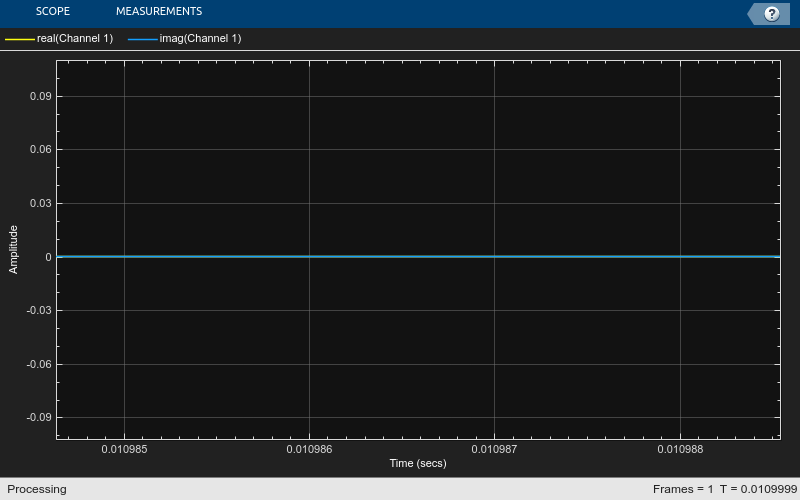

timeScope(waveform);

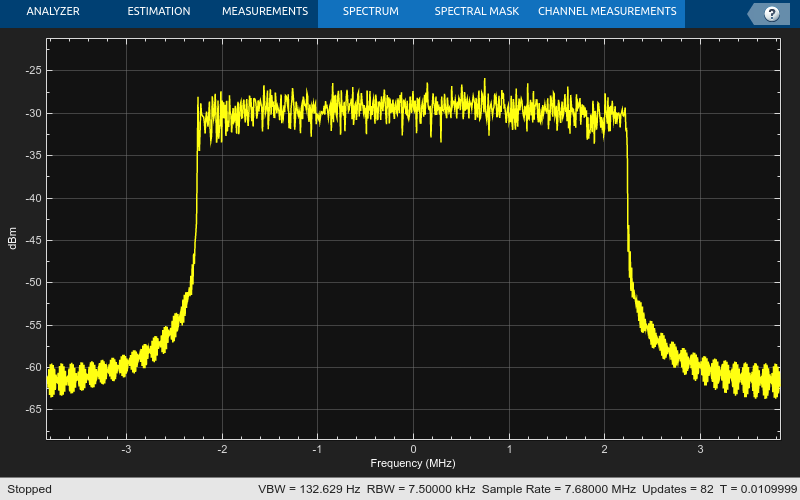

release(spectrum);

spectrum(waveform);
release(spectrum);

%% Transmit waveform over the air
masterClockRate = 7680000;
interpolationFactor = 1;
usrpTx = comm.SDRuTransmitter(Platform='B200');
usrpTx.SerialNum ='3293CEA';
usrpTx.CenterFrequency = frequencyBand;
usrpTx.Gain = -txGain;
usrpTx.ChannelMapping = 1;
usrpTx.LocalOscillatorOffset = 1;
usrpTx.PPSSource = 'Internal';
usrpTx.ClockSource = 'Internal';
usrpTx.MasterClockRate = masterClockRate;
usrpTx.InterpolationFactor = interpolationFactor;
usrpTx.TransportDataType = 'int16';
usrpTx.EnableBurstMode = false;

% Provide trigger time
usrpTriggerTime = 10;

tx.EnableTimeTrigger = true;
tx.TriggerTime = usrpTriggerTime;




rx    = hSDRReceiver("B200"); % SDR receiver object

Checking radio connections...


rx.CenterFrequency = frequencyBand; 

Unrecognized function or variable 'frequencyBand'.

rx.SampleRate      = Fs;
rx.Gain            =  rxGain; 

framesToCapture    = 11;

% Derived parameters
captureDuration = milliseconds(10)*(framesToCapture+20); % Increase capture frame by 1 to account for a full frame not being captured



waveform = repmat(waveform, 1, 1);
usrpTx(waveform);



Transmission stopped.



rxWaveform = capture(rx,captureDuration);

## Establishing connection to hardware. This process can take several seconds.


fprintf('Transmission stopped.\n')
release(usrpTx);
fprintf('Recieving stopped.\n')

Recieving stopped.


release(rx);

EVM stats for BWP idx : 1
PDSCH RMS EVM, Peak EVM, slot 1: 4422.050 106050.177%
PDSCH RMS EVM, Peak EVM, slot 2: 4802.457 109408.948%
PDSCH RMS EVM, Peak EVM, slot 3: 7646.493 144113.837%
PDSCH RMS EVM, Peak EVM, slot 4: 5366.036 110841.664%
PDSCH RMS EVM, Peak EVM, slot 5: 9690.577 222129.901%
PDSCH RMS EVM, Peak EVM, slot 6: 3740.990 60932.081%
PDSCH RMS EVM, Peak EVM, slot 7: 8398.837 168923.582%


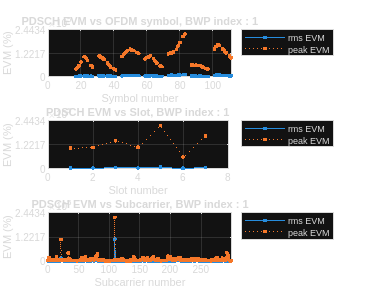

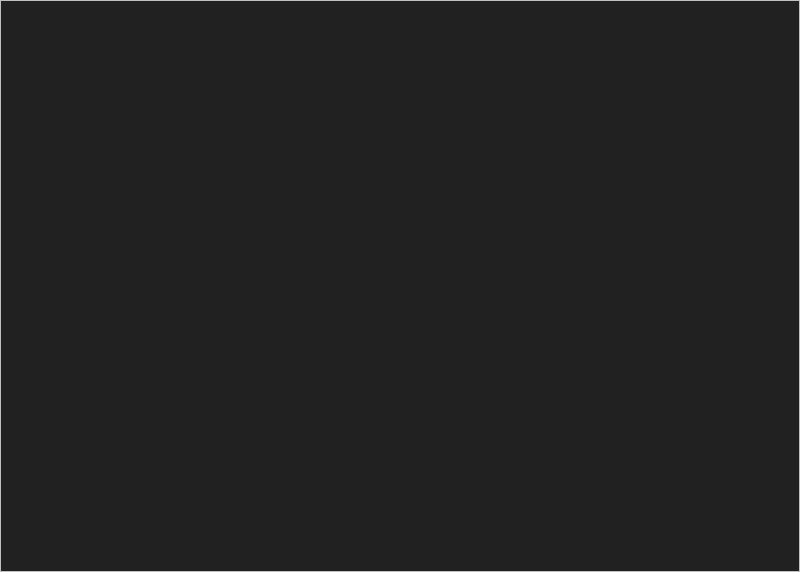

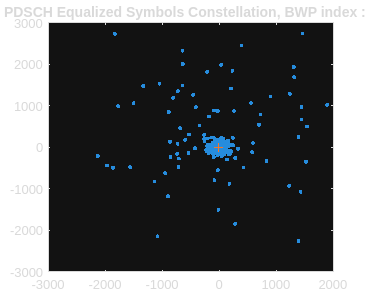

Averaged overall PDSCH RMS EVM: 6636.738%
Overall PDSCH Peak EVM = 222129.9011%


rcwavegen = hNRReferenceWaveformGenerator(rc,bw,scs,dm);
cfgDL = rcwavegen.Config;

cfg = struct();
cfg.PlotEVM = true;             % Plot EVM statistics 
cfg.DisplayEVM = true;          % Print EVM statistics
cfg.Label = rc;                 % Set to TM name of captured waveform
cfg.SampleRate = 30.72e6;%rx.SampleRate; % Use sample rate during capture
cfg.IQImbalance = true;
cfg.TargetRNTIs = rnti;
cfg.CorrectCoarseFO = true;
cfg.CorrectFineFO = true;
cfg.ExcludeDC = true;

[evmInfo,eqSym,refSym] = hNRDownlinkEVM(cfgDL,rxWaveform,cfg);